# Machine Learning: Mobile Ad-hoc Network Routing Protocol

## Neural Networks Learning

- Node's decision on the timing of "Hello Message" broadcasts

- Routing of packets to neighbors based on geographic, mobility, and network traffic information exchanged

- Node's decision to limit the transmit power to maintain links to the first closest neighbor for reduced interference and coverage overlap between network branches (Game Theory)

- Node's decision for Store-Carry-Forward during the transitions between reactive and greedy in an RGR algorithm

- Predicting the type of environment based on network state with the perspective of each node's currently available information for switching between sparsely and contention based approach (region-specific model?! denser populated areas also tend to be flatter, and vice versa)

- Predicting the quality and the straight-line-of-sightness of a link and hence its reliability

- Predict the probability that in a given region/terrain, the line-of-sight distance will be obstructed and hence decrease the weight or quality expectation of the link

### Files needed for this exercise

- `manet.mlx` - MATLAB Live Script that steps you through the study implementation

- `numify.mlx` - MATLAB Live Function that converts string values into unique integers (used to convert bus and line names into unique incrementing integers)

- `treatedGPSDataWithoutEmptyLinesSeparateColumns.csv` - Comma-separated text file containing Rio de Janeiro bus dataset from [Kaggle](https://www.kaggle.com/igorbalteiro/gps-data-from-rio-de-janeiro-buses) (the [original source](https://l.facebook.com/l.php?u=http%3A%2F%2Fdadosabertos.rio.rj.gov.br%2FapiTransporte%2Fapresentacao%2Frest%2Findex.cfm%2FobterTodasPosicoes%3Ffbclid%3DIwAR0lKF84BOUukCp33OfiEsX2qDvFocmiX_-hYkw_38oOPDD_XxDdCQXBUuo&h=AT0z08BWTFxSl2Ahh1NN_PDK0ab69uLs5slSBSs0npLTc6Thc89AkWtERXVIMD_2yWdP1_PFAGDbKIyOxvAJhG7Ot5ZoYWck_kEF5VaypLB_JB5Lnq7h1SiwruE8orIVHmXt9TnG1mhLUg) provides real-time tracking information for the buses up till now)

### Toolboxes needed for this exercise

- `Mapping Toolbox` - provides all the GIS functionality (interpolation, 3D mapping and visualisation)

- `Parallel Computing Toolbox` - parallelizes work on Big Data across the compute cluster

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the '`Machine Learning - MANET`' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir


.           ..          .git        manet.mlx   numify.mlx  



#### Remarks

Code commented out with triple `%%%` must be uncommented when working with Big Data not fitting in memory

## TODO - Checklist

- Find distances between nodes at each sampling instance or resample/synchronize timetable with non-linear interpolation of datum

- Fill dataset with interpolated values to obtain consistent network snapshots of each existing node or assume that outside of recorded times, busses have no connection/are powered off

- Time synchronize data (interpolate by snapping to vector tiles of roads)

- Add elevation information

- Monte Carlo simulation of the network to label routes as ideal or not (at limit to infinity converges to real behavior of the network)

- Test the prorotype in-memory implementaiton with `Tall Arrays` for Big Data

## Data Preprocessing

We begin by creating a `Datastore` object of the [Kaggle](https://www.kaggle.com/igorbalteiro/gps-data-from-rio-de-janeiro-buses) dataset of Rio de Janeiro busses.

% ds = tabularTextDatastore('testfile.csv',...
%                             'SelectedFormats',{'%{MM-dd-yyyy}D', '%{HH:mm:ss}D', '%q', '%q', '%f', '%f', '%f'},...
%                             'SelectedVariableNames',{'Date', 'Time', 'Order', 'Line', 'Latitude', 'Longitude', 'Speed'});
% ds.ReadSize = 100000;
% preview(ds)
% prototype dataset contains 30 seconds of data between 
% 09:12:25 and 09:12:55 to simplify the development stage
tt = readtable('testfile.csv','TextType',"string","Format",['%f','%{MM-dd-yyyy}D', '%{HH:mm:ss}D', '%q', '%q', '%f', '%f', '%f']);

We then create a `Tall Array` out of the `Datastore`, merge date-time columns into a single MATLAB timestamp, convert long bus and line strings into unique integers, and finally turn the array into a `Timetable` for easier preprocessing of time-series data.

% % % tt = tall(ds);
tt.Datetime = datetime(tt.Date.Year, tt.Date.Month, tt.Date.Day, tt.Time.Hour, tt.Time.Minute, tt.Time.Second);
tt(:,1:2) = [];

min_lat = min(tt.Latitude);
min_lon = min(tt.Longitude);
max_lon = max(tt.Longitude);
max_lat = max(tt.Latitude);

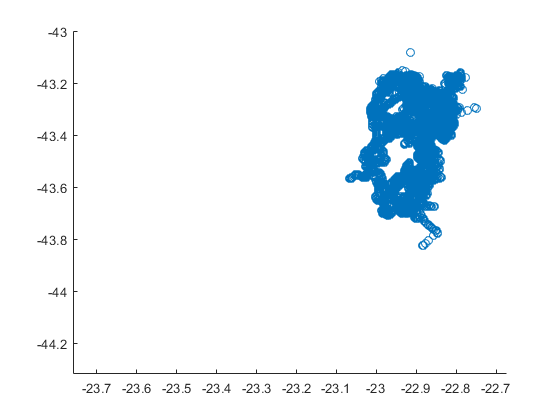

scatter(tt.Latitude,tt.Longitude);

% % % [min_lat,min_lon,max_lat,max_lon] = gather(min_lat,min_lon,max_lat,max_lon)

${\textrm{Latitudes}}_{12\textrm{GB}} \in \left\lbrack -33\ldotp 395523;36\ldotp 479530\right\rbrack$, ${\textrm{Longitudes}}_{12\textrm{GB}} \in \left\lbrack -110\ldotp 1463;127\ldotp 886\right\rbrack$

orders = unique(tt.Order);
lines = unique(tt.Line);

tt.Order = numify(tt.Order,orders);
tt.Line = numify(tt.Line,lines);
orders = unique(tt.Order);
lines = unique(tt.Line)

TT = table2timetable(tt)

TT = 1000000×8 timetable
      Time       Order        Line      Latitude    Longitude    Speed          Datetime          order    line
    ________    ________    ________    ________    _________    _____    ____________________    _____    ____

    00:03:05    "B27178"    "639.0"     -22.817      -43.302       0      25-Jan-2019 00:03:05    1539     212 
    00:07:29    "D13324"    "731.0"     -22.874      -43.358      37      25-Jan-2019 00:07:29    4259     238 
    00:07:59    "D13324"    "731.0"      -22.88      -43.358      37      25-Jan-2019 00:07:59    4259     238 
    00:17:31    "D13150"    "SV790"     

% checks how many time frames are present in the dataset
t_samples = unique(TT.Datetime);

[h,m,s] = hms(tt.Datetime(end)-tt.Datetime(1));
s = h*3600+m*60+s

s = 47109

#### *Optional*

The code below creates a cell structure which is useful in case building distance vectors from the two geolocation points is desired. If not needed, the section can be omitted (*Must be checked for compatibility with `Tall Arrays`)

% instantiates a cell array of cell arrays of empty matrices
dist_cell = cell(size(t_samples,1),1);
for i = 1:size(t_samples,1)
    dist_cell{i} = cell(size(orders,1));
end

% fills cell array of Nx1 (corresponds to frames) of MxM cell arrays
% (corresponds to relationships between 2 corresponding nodes) of 2x2
% matrices (corresponds to the geolocation vector) with 2 geolocation
% points
for i = 1:size(t_samples,1)
    TT_chunk = TT(t_samples(i),:);
    for j = 1:size(TT_chunk,1)
        for k = 1:size(TT_chunk,1)
            dist_cell{i}{TT_chunk.order(j),TT_chunk.order(k)} = [TT_chunk.latitude(j),TT_chunk.longitude(j);
                                                                TT_chunk.latitude(k),TT_chunk.longitude(k)];
        end
    end
end

We sweep through the entire dataset frame-by-frame and derive for each pair of nodes the distance between them.

*Note:* `distance()` omits information about altitude difference. For realistic simulations, it is neccesary to synthesize appropriate altitude data corresponding to each node's geolocation, which will then be used to derive the line-of-sight distance between the nodes.

% instantiates a 3D matrix (-1 corresponds to no datum)
dist_mat = ones(size(orders,1),size(orders,1),size(t_samples,1))*(-1);

% fills 3-dimensional array with distance measures between corresponding
% indexing nodes
for i = 1:size(t_samples,1)
    TT_chunk = TT(t_samples(i),:);
    for j = 1:size(TT_chunk,1)
        for k = 1:size(TT_chunk,1)
            dist_mat(TT_chunk.order(j),TT_chunk.order(k),i) = deg2km(distance(TT_chunk.latitude(j),TT_chunk.longitude(j),...
                                                                TT_chunk.latitude(k),TT_chunk.longitude(k)));
        end
    end
end

% % % [orders,lines,num_orders,num_lines] = gather(orders,lines,size(orders,1),size(lines,1));

This next part determines the output based on the newly created distance-time tensor.

transmission_range =0;
threshold = 0.5;

output = determine_output(dist_mat,tt.datetime,tt.Order_num,t_samples,orders,transmission_range,threshold);